In our computer lab we used a Radial Basis Function to act as a surrogate for the expensive ODE predator prey model (implemented in function *model2*). In that computer lab a very important feature of the method was the choice of the smoothing parameter. In the original computer lab we picked this parameter by eyeballing it, but in this assignment we will walk you through a method to find a good value - the method of Cross Validation. 

We will be looking at a slightly different problem - fitting model to data.

## Set-Up - Computer Lab Background

In this live script we are interested in the Preditor-Prey model under uncertainty in the model inputs. 

## Preditor Prey Model

I have setup a function to solve the preditor prey ODE model


$$\begin{array}{l}
\frac{\partial \textrm{owl}}{\partial t}=\textrm{a2}\times \;\;\textrm{owl}\;\times \;\textrm{rat}-\textrm{a1}\;\times \;\textrm{owl}\;\\
\frac{\partial \textrm{rat}}{\partial t}=\textrm{a3}\times \textrm{rat}-\textrm{a2}\times \textrm{owl}\times \textrm{rat}
\end{array}$$


where the variable, owl is number (or concentration) of owls and rat is the number of rats

The code for this is available towards the end of the script where the function model2 is defined. 

The function model2 has input paramters a1, a2, a3, owl0, rat0 and tfinal and outputs a timeseries of y(t) for t in [0, tfinal] where y(:,1) represents the owl population and y(:,2) the rat population. We could make all 5 parameters uncertain, but lets just stick to perturbing a1 and a2 (easier to visualise). 

clear all

%Fix seed of random number generator
%rng(1)

%Fixed parameter values for problem
owl0 = 10;
rat0 = 5;
a3 = 1.5;
tfinal = 12;



This ODE model is defined in the function model2 towards the end of this script.

## RBF to fit to data

#### Synthetic data

Since we don't have real data, we will create some synthetic ones

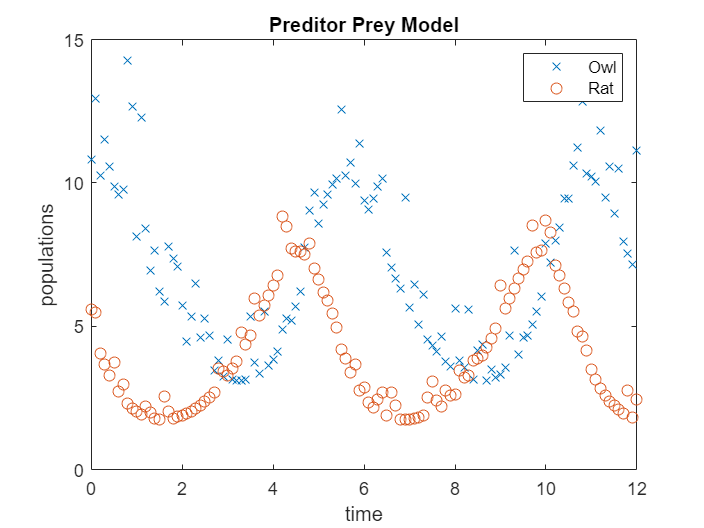

a1 = 1;
a2 = 0.25;

[t,y]= model2(a1, a2, a3, owl0, rat0, tfinal);  % run the model with 
y(:,1) = y(:,1);
y(:,2) = y(:,2);

owldata = y(:,1) + max(1.5*randn(size(y(:,1))),0); % 扰动
ratdata = y(:,2)+ max(0.7*randn(size(y(:,2))),0);

plot(t, owldata, 'x')
hold on
plot(t, ratdata, 'o')
xlabel('time')
ylabel('populations')
title('Preditor Prey Model')
legend('Owl','Rat')
hold off

#### Sample Input Parameters

We now use 50 samples in a1 and a2 space, and calculate the least square fitting error for each of these samples

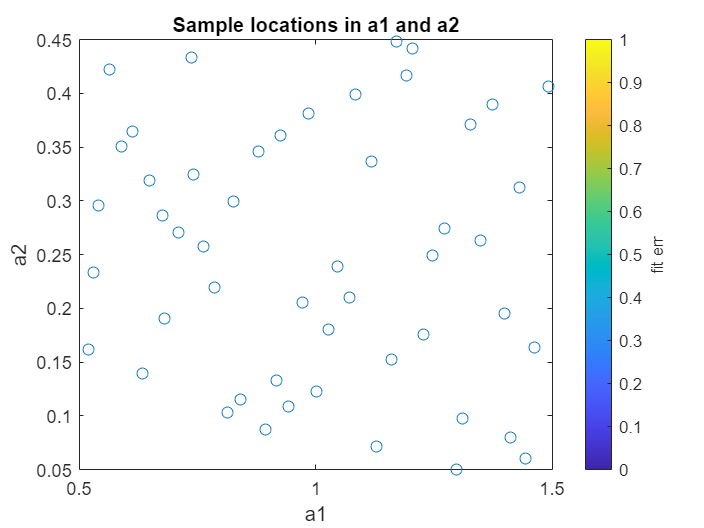

% local settings
ninit = 50;   

range = [0.5, 0.2]; % range of our sampling.

% create samples
Q = [a1,a2] + range.*(2*lhsdesign(ninit,2,'iter',20)-1);

% plot sampling plan
plot(Q(:,1),Q(:,2),'o') 
h = colorbar;
xlabel('a1')
ylabel('a2')
ylabel(h,'fit err')
title('Sample locations in a1 and a2')

#### Calculate data fitting error (objective function we want to minimise) for Sample Points

% pre-allocate the tv values
j = ones(ninit,1);

% run model2 for initial sampling
for k = 1:ninit
    j(k) = measure_err(Q(k,1),Q(k,2),a3,owl0,rat0,tfinal,owldata,ratdata);
end

#### Calculate Radial Basis Function Approximation to fiterr as function of a1 and a2

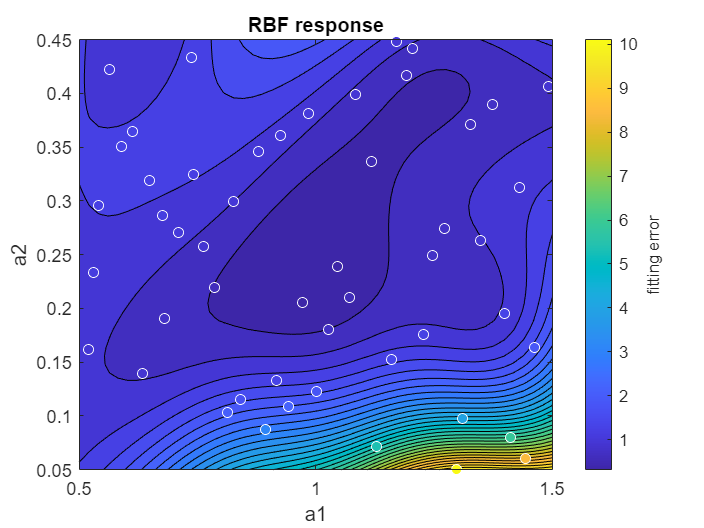

% Smoothing parameter for the RBF function. 
theta = 0.25; 

% Setup grid points around (a1,a2)
[Xi1,Xi2] = meshgrid(linspace(a1-range(1),a1+range(1),50),linspace(a2-range(2),a2+range(2),50));
xi = [reshape(Xi1,numel(Xi1),1) reshape(Xi2,numel(Xi2),1)];


% make RBF prediction
yi = rbf(Q, j, xi, theta); 
Yi = reshape(yi,size(Xi1));

% Plot RBF surface with 30 contours
contourf(Xi1,Xi2,Yi,30)
hold on
scatter(Q(:,1),Q(:,2),30,j,'filled')
scatter(Q(:,1),Q(:,2),30,j,'wo')
hold off
h = colorbar;
xlabel('a1')
ylabel('a2')
ylabel(h,'fitting error')
title('RBF response')

**Improve Radial Basis Function Approximation and then Minimise It **

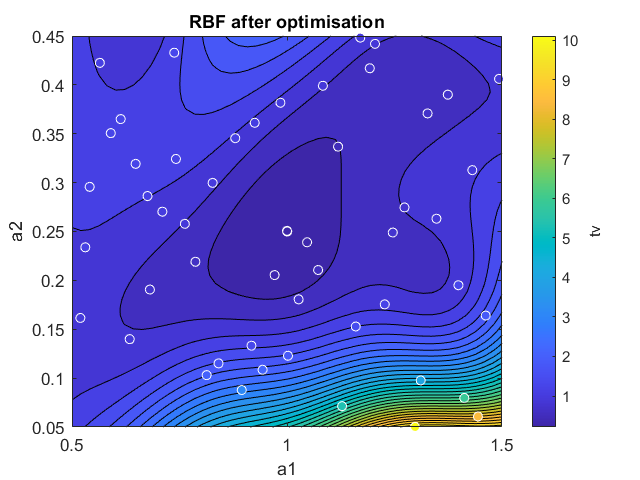

%Number of Iterations for Improvement
nopt = 5;
Opt_Q = Q;
Opt_j = j;
for k = 1:nopt
    
    % MC-type optimisation of the RBF
    xi = [a1,a2]+(range - range.*rand(1e6,2)); 
    yi = rbf(Opt_Q, Opt_j, xi, theta);
    [~,id] = min(yi); % expected min of surrogate
    newQ = xi(id,:); % expected location of min of surrogate
    
    % run model at expected min
    newj = measure_err(newQ(1),newQ(2),a3,owl0,rat0,tfinal,owldata,ratdata); 
   
    
    % add new solve to data
    Opt_Q = [Opt_Q ; newQ];
    Opt_j = [Opt_j  ; newj];

end

% Plot the results
[Xi1,Xi2] = meshgrid(linspace(a1-range(1),a1+range(1),50),linspace(a2-range(2),a2+range(2),50));
xi = [reshape(Xi1,numel(Xi1),1) reshape(Xi2,numel(Xi2),1)];
yi = rbf(Opt_Q, Opt_j, xi, theta); 
Yi = reshape(yi,size(Xi1));

figure()
contourf(Xi1,Xi2,Yi,30)
hold on
scatter(Opt_Q(:,1),Opt_Q(:,2),30,Opt_j,'filled')
scatter(Opt_Q(:,1),Opt_Q(:,2),30,Opt_j,'wo')
hold off
h = colorbar;
xlabel('a1')
ylabel('a2')
ylabel(h,'tv')
title('RBF after optimisation')

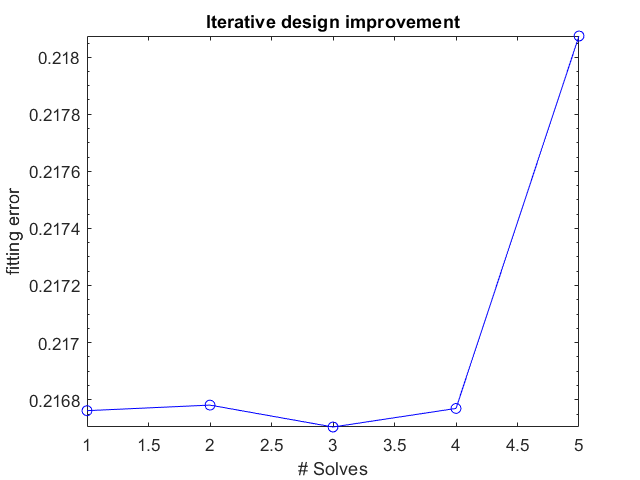


figure()
semilogy(Opt_j(ninit+1:end),'bo-')
xlabel('# Solves')
ylabel('fitting error')
title('Iterative design improvement')

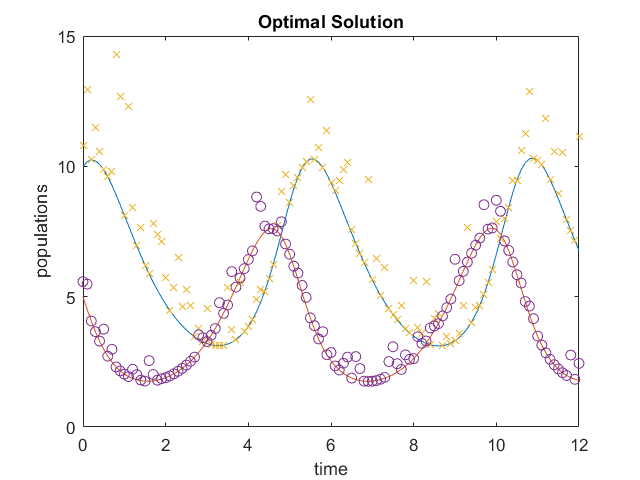


% Plot optimal
[jmin, jarg] = min(Opt_j);
rbfj = rbf(Opt_Q, Opt_j, Opt_Q(jarg,:), theta);

[t,y] = model2(Opt_Q(jarg,1), Opt_Q(jarg,2),a3,owl0,rat0,tfinal);

plot(t,y)
hold on
plot(t, owldata, 'x')
plot(t, ratdata, 'o')
hold off

title('Optimal Solution')
xlabel('time')
ylabel('populations')


fprintf('Optimal sample point Q = %g , %g \n',Opt_Q(jarg,1), Opt_Q(jarg,2))

Optimal sample point Q = 1.00032 , 0.250005 


fprintf('Optimal fit err value %g \n',jmin)

Optimal fit err value 0.216705 


fprintf('Optimal rbf fit err value %g \n',rbfj)

Optimal rbf fit err value 0.245153 


The above code performs the RBF optimisation to fit to data when  a3, owl0, rat0 and tfinal are fixed and we sample around the choices of a1, a2 that achieve the constant state. 

We will now redo the above analysis with a method for choosing the smoothing parmater of the RBF approximation - $\theta$. The central idea is to split the samples in a1 and a2 into Training Data and Test Data, we then train our Approximation using the training set and compare the approximation to the values of the test set for each theta value. We can then find the theta value that minimises the difference, thus finding the optimal theta value. 

## 1

Reproduce the sampling of the parameter space using lhsdesign for Q, but now creating a Test set - QTest and a Training set QTrain. Use the same a1 and a2 base values, and the same range around them. For this assignment use Q as the training set of 40 samples and a test set of 10 samples.

*Hint: lhsdesign is not random sampling. You can not generate 50 samples altogether and split it into two sets. * 

% create samples
Q = [a1,a2] + range.*(2*lhsdesign(ninit,2,'iter',20)-1);

## 2

Add a function (remember that function definitions go below)  called cross_validation that has the structure for you to fill out using the rbf function below

*function cv = cross_validation(QTrain, errTrain, QTest, errTest, theta)*

*	% Calculate rbf values at Qtest locations*

*	% using the training set QTrain, errTrain *

*	rbferr = .... *

*	cv = norm(rbferr-errtest)*

*end*

This function takes training and test sets as well as the parameter value theta and tests how well the surrogate model trained using QTrain and tvTrain approximates the Test data QTest and tvTest.

## 3

Using the function you just created, test various values of theta to find how the model generated by the theta behaves as theta changes - allowing us to identify optimal value of it. Plot the cross validation value versus theta. Try 200 theta values in the [0.001,10] range. 

Recommend a Theta Value. Justify your recommended value. 

## 4

Check your recommended Theta Value by reproducing the data fitting problem and shown above, using your recommended Theta Value and your Training data QTrain and errTrain.

Plot the owl and rat population over time to demonstrate the fit to data.

Is the fitting error with the recommended Theta always lower than our original choice $\theta =0\ldotp 25$? Why or why not? Is a1=1 and a2=0.5 always the best fit?

(HINT: you can rerun the notebook many times to check. Each time you will generate a different set of samples)

Will that affect your recommended Theta? Note that our computational budget only allows you to run the model 55 times.

## Function Definitions

In live scripts all the function definitions have to be placed at the end of the script.

### Cross Validation

function cv = cross_validation(Q, errQ, Qtest, errtest, theta)
% Calculate rbf values at Qtest locations
% using the training set Q, errQ

end

### Model2

Code for Preditor Prey model and wrapper to allow parameters to be passed. Also a function measure_err to the total fitting error of the solution to data. 

function [t,y]= model2(a1, a2, a3, owl0, rat0, tfinal)
    t = 0.0:0.1:tfinal;
    [t,y] = ode15s(@(t,y) fun2(t,y,a1,a2,a3), t, [owl0, rat0]);
end

function F = fun2(t, y, a1, a2, a3)
    owl = y(1);
    rat = y(2);
    F = zeros(2,1);
    dowl =  a2*owl*rat - a1*owl;
    drat =  a3*rat - a2*owl*rat;
    F(1) = dowl;
    F(2) = drat;
end


### Function to measure fitting error

function err = measure_err(a1, a2, a3, owl0, rat0, tfinal, owldata, ratdata)
    
    [t,y] = model2(a1, a2, a3, owl0, rat0, tfinal);
    
    y1 = y(:,1);
    y2 = y(:,2);
    
    normfactor_owl = mean(owldata)^2 * numel(owldata);
    normfactor_rat = mean(ratdata)^2 * numel(ratdata);
    
    err = (y1-owldata).^2 ./ normfactor_owl  + (y2 - ratdata).^2 ./ normfactor_rat; 
    err = sqrt(sum(err));
end



### RBF Functions

function yi = rbf(x,y,xi,theta)

%RBF Radial basis functions prediction.
%   yi = rbf(x,y,xi,theta) provides the radial basis functions prediction
%   yi, at locations xi, based on training data y at locations x. The
%   kernel size is given by theta.


% normalize

%xmean = mean(x);
%x = x ./ xmean;
%xi = xi ./ xmean;

ymean = mean(y);
y = y - ymean;

% create matrices
Phi = kernel(x,x,theta);
R = diag(1e-4*ones(size(x,1),1));
Psi = kernel(x,xi,theta);

% compute weights
weight = (R+Phi)\y;

% interpolate
yi = Psi*weight;

% denormalize
yi = yi + ymean;

end

function C = kernel(x1,x2,theta)

% Initialize distance-squared
DistSquared = zeros(size(x2,1),size(x1,1));

% Loop over dimensions
for k = 1:size(x1,2)
    [X1,X2] = meshgrid(x1(:,k),x2(:,k));
    DistSquared = DistSquared + (X1-X2).^2;
end

% Compute Gaussian kernel
C = exp(-0.5*DistSquared*theta^-2);

end
